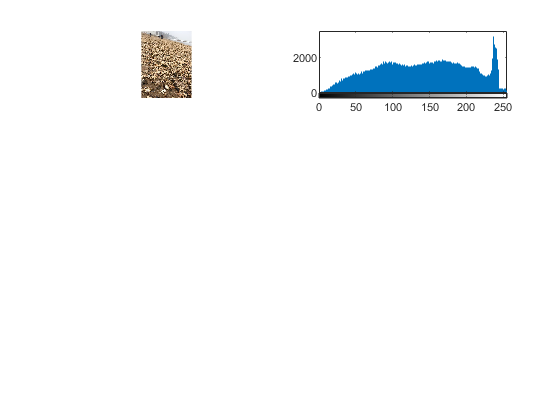

imMedian = uint8
134

IS DARK


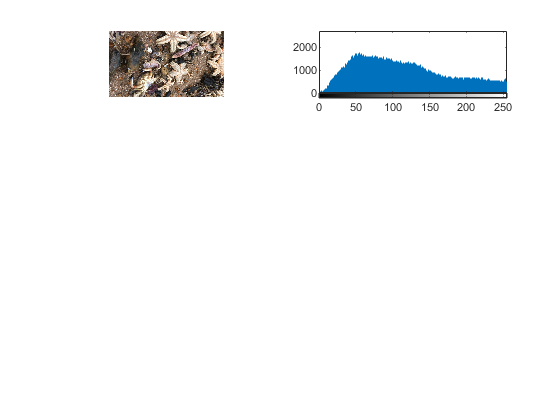

imMedian = uint8
100

IS DARK


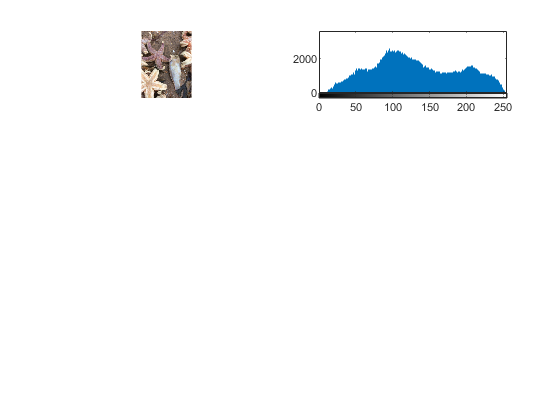

imMedian = uint8
121

IS DARK


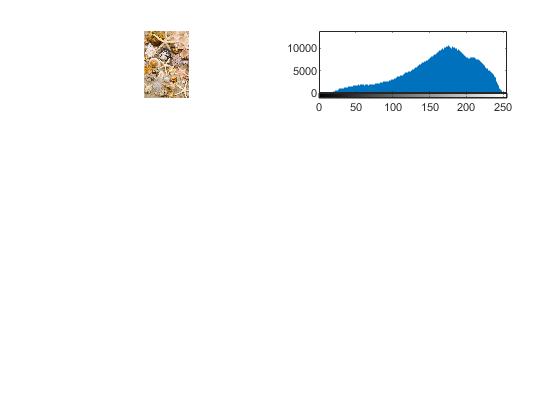

imMedian = uint8
163

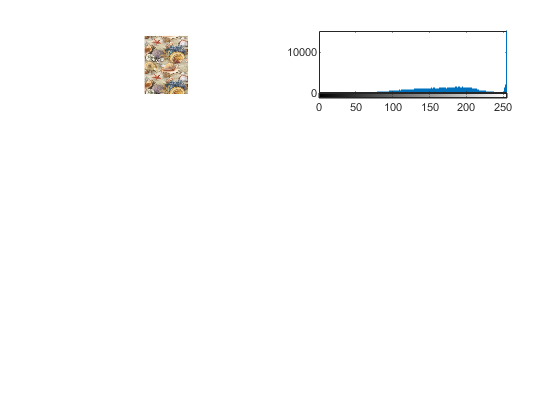

imMedian = uint8
207

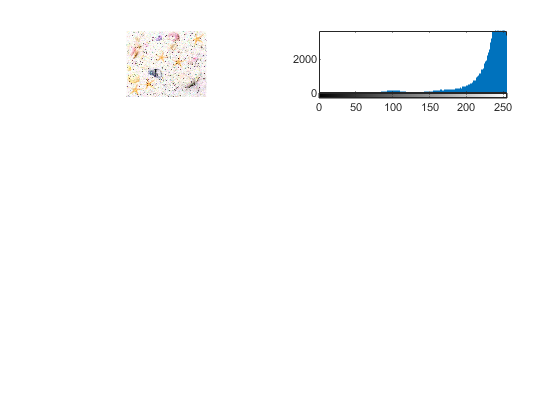

imMedian = uint8
238

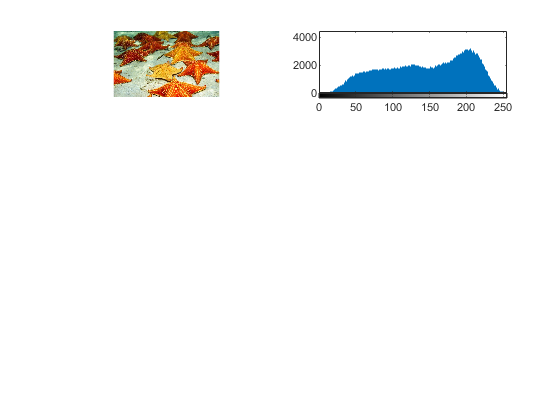

imMedian = uint8
151

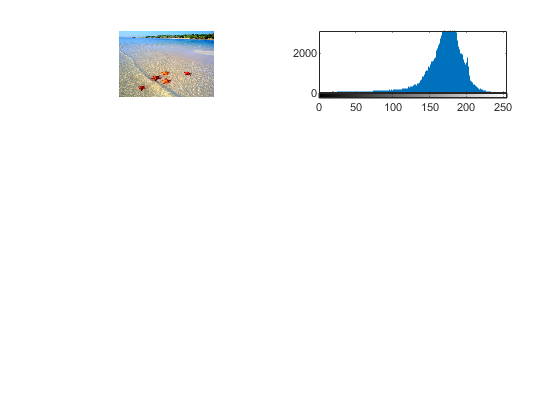

imMedian = uint8
172

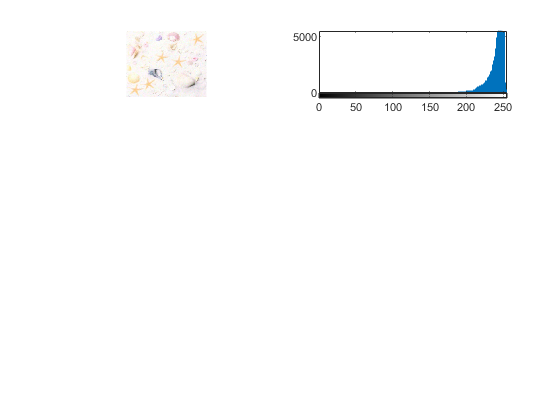

imMedian = uint8
244

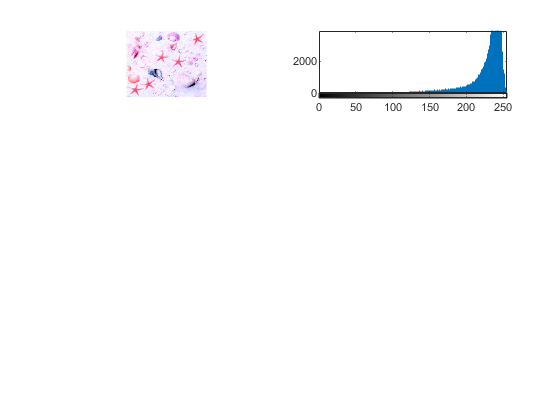

imMedian = uint8
242

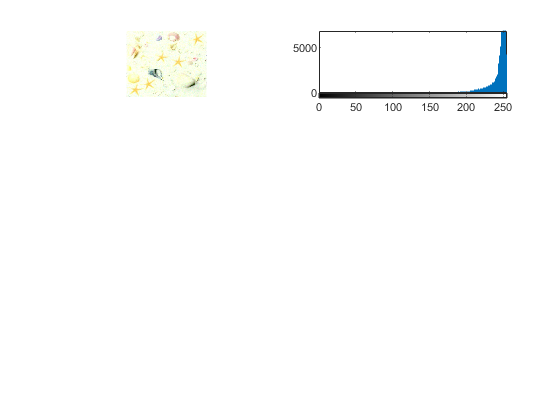

imMedian = uint8
247

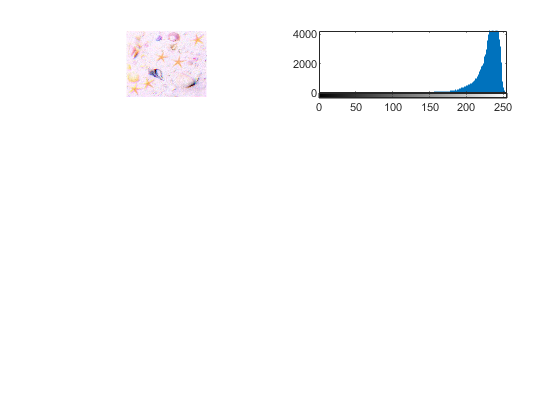

imMedian = uint8
238

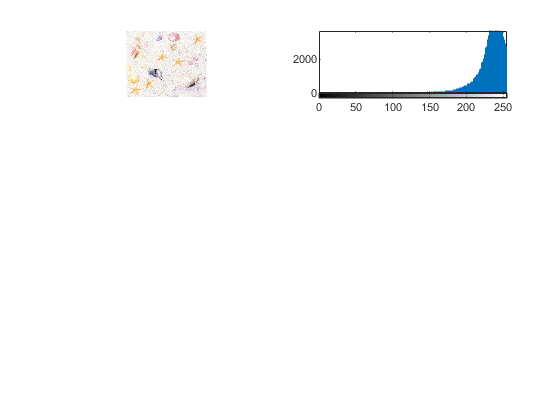

imMedian = uint8
236

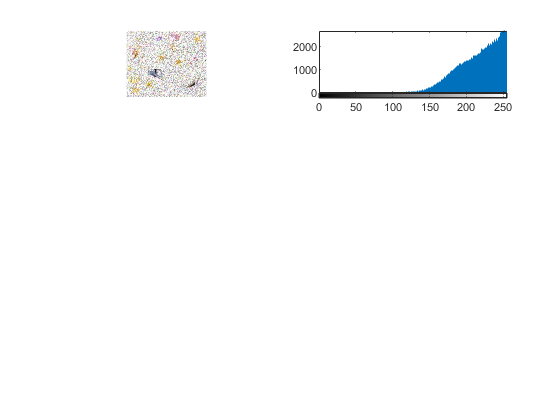

imMedian = uint8
221

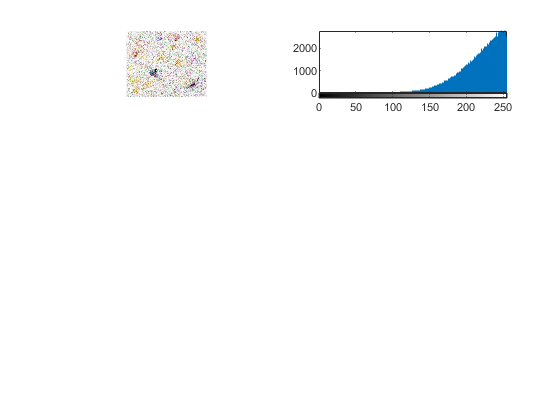

imMedian = uint8
224

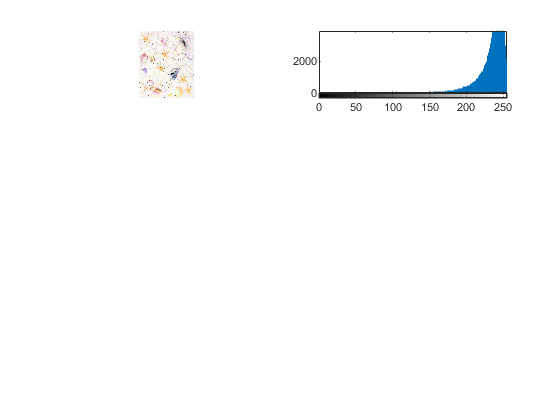

imMedian = uint8
238

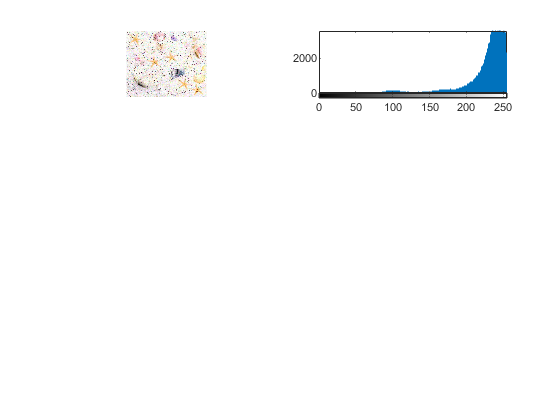

imMedian = uint8
236

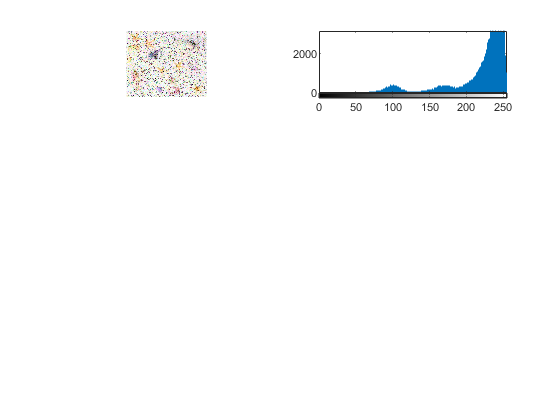

imMedian = uint8
231

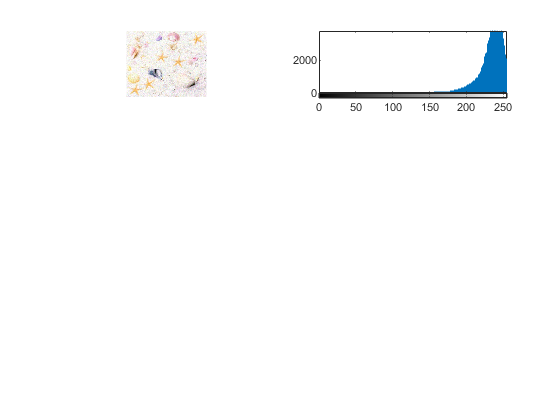

imMedian = uint8
237

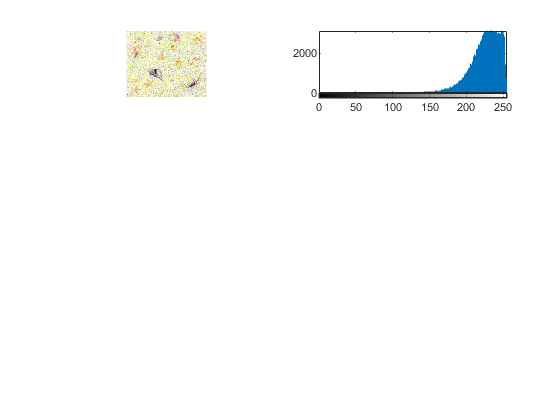

imMedian = uint8
224

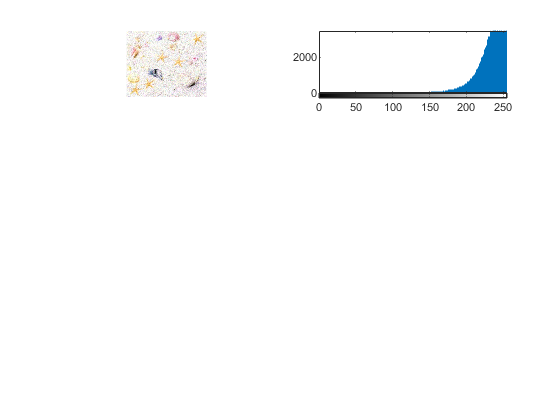

imMedian = uint8
236

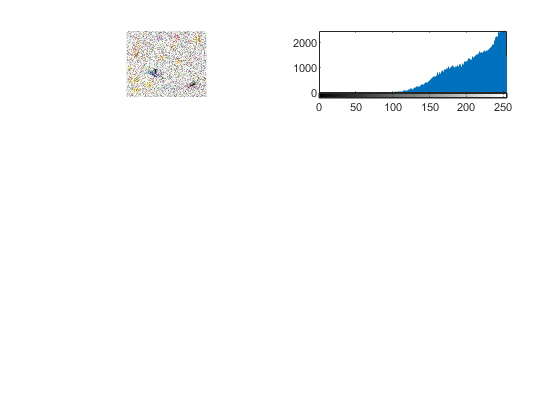

imMedian = uint8
214

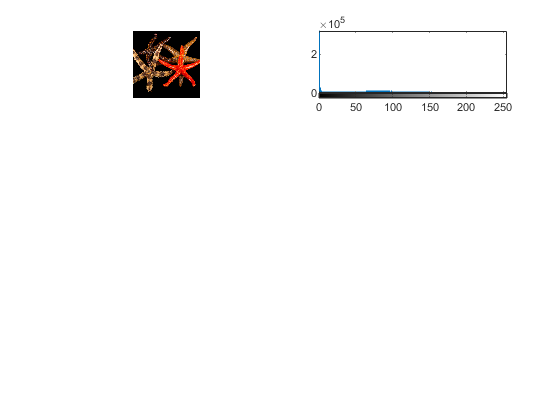

imMedian = uint8
0

IS DARK


files = GetFilesInSubDir("images");

r = 4;
c = 2;
for i = 1:numel(files)
    filepath = files(i);
%     disp(filepath)
    im = imread(filepath);
    
    figure
    subplot(r,c,1);
    imshow(im);
    subplot(r,c,2);
    allChHist = imhist(rgb2gray(im));
    imhist(rgb2gray(im));
    IsDark(im);
end

function filepaths = GetFilesInSubDir(subDir)
files = dir(subDir);
files = files(~ismember({files.name}, {'.', '..'})); % Remove navigation elements from struct.
filepaths = subDir + "\" + {files.name};
end

function bool = IsDark(im)
    grayScaler = 1;
    if (max(im(:)) <= 1)
        grayScaler = 255;
    end
    
    imMedian = median(im(:));
    if (imMedian <= (135 / grayScaler))
        bool = true;
        disp("IS DARK");
    else
        bool = false;
    end
end

function [BW,maskedRGBImage] = RGBThresh(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 11-May-2020
%------------------------------------------------------
[r,g,b] = imsplit(RGB);
gMean = mean2(g)
gStd = std2(g)
bMean = mean2(b)
bStd = std2(b)
bLogStd = log(bStd);

bVal = 255;
gVal = 255;
bStdMultiplier = round(((bLogStd * 0.1) * (bLogStd * 0.4)),2,'significant');

if (gMean < bMean)
    % Mostly reduce green channel.
    gVal = floor(gMean - (gStd * bStdMultiplier))
    if (bMean >= 200 && bMean <= 235)
        bVal = bMean
    end
else
    % Mostly reduce blue channel.
    bVal = floor(bMean - (bStd * bStdMultiplier))
    if (gMean >= 200 && gMean <= 235)
        gVal = gMean
    end
end

% Convert RGB image to chosen color space
I = RGB;

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.000;
channel1Max = 255.000;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = gVal;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = bVal;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end